# **GEO-Synchronous orbit Autonomous Rendezvous and Docking (AR&D) Mission Design**

**WorkerInSpace**

**Hongseok Kim**

**2025/06/25**

## I. Introduction and Scope

  랑데뷰 도킹 미션설계 과정은 서비싱 위성이 GTO (GEO-Transfer Orbit)에 위치하였다고 가정하고 시작한다. 이때, GTO의 inclination angle은 28.3 deg (Cape Canaveral), 6 deg (프랑스령 기아나) 크게 두 후보군으로 설정한다. 최종적으로는 Target Satellite에 완전히 도킹하는 것을 목표로 한다. 궤도 이동 과정은 총 4 step으로 나눌 수 있다.

- **Phase 1: **GTO to near-GEO transfer (Orbit Raise Process)

- **Phase 2: **Co-Elliptic Rendezvous with Hohmann Raises

- **Phase 3: **Walking Safety Ellipse (WSE) Approach

- **Phase 4: **Capture Axis Approach

  각 기동에 대하여 우선 주어진 input condition에 맞는 해석적인 solution을 Matlab을 활용하여 산출하여 해당 궤적을 그리고, 필요한 Delta-V의 initial 값과 각 LVLH/body축에 따른 Delta-v profile을 도출한다. 그리고, 해석적인 simulation에서 여러가지 케이스에 따른 궤적들을 산출한다. 이때, chaser 위성과 target 위성 사이의 상대 위치에 관한 요구사항 (visibility, sun phase angle) 및, chaser 위성과 지상 사이의 교신 여부에 관한 요구사항 등을 각 궤적에 반영하여, 해당 요구사항의 만족 여부를 판별한다. 또한 최적의 delta-V 및 impulse profile에 관한 분석 결과도 산출한다. 또한, delta-v 기동에 대한 미세한 오차를 산출하여, 실제 형성 궤도가 목표지점과 얼마만큼의 차이를 내는지 확인하고, 해당 차이가 있더라도, delta-V의 큰 변동 없이 임무수행이 가능한지 확인한다. 이는 Orbit의 Mission Stability와도 관계가 있을 것으로 예상된다.  

  Matlab을 통하여 산출한 해석적 궤도에 관한 프로파일을 STK 시뮬레이션에 적용하여 유사한 결과의 궤도를 도출 할 수 있는지 cross-check를 진행하며, 실제적인 궤도 환경에서 해석적 해와 유사하게 궤도 형성이 가능한지 확인한다. 이때 그 오차 범위를 정량적으로 산출한다. 

  현재 수행하고자 하는 궤도 설계는 Chemical Propulsion을 사용한 Impulsive Burn을 가정한 궤도 설계이다. 다만 연료 효율을 고려하여 Electric Propulsion을 사용한 Finite Burn을 사용한 궤도 설계를 수행하여야 하는데, 이는 기존에 Impulsive Burn개념을 사용한 동일한 궤적을 Finite Burn으로 대체하여, 비슷한 Delta-V로 해당 궤적을 만족시킬 수 있는지 확인하는 방식으로 사용한다. Impulsive Burn은 단시간 추력기를 기동하여 한순간에 Delta-V를 바로 바꾸는 것이고, Finite Burn은 장시간 추력기를 기동함으로서 점차적으로 Delta-V를 기동하는 것을 의미한다.

## II.  Phase 1: GTO to near-GEO transfer (Orbit Raise Process)

### II.1 Delta-V Orbit raise and Inclination change at RAAN

#### II.1.1 Delta-V from orbit raise

clear; clc;

% Orbit Contstant
J2 = 0.00108248;
R_Earth = 6378.1363;
mu = 398600.4415;

%% Define Initial Orbit Parameter
SMA = 24434.864; 
ecc = 0.728693;
inc = 28;
RAAN = 0;
AOP = 0;
theta = 180;
orbit_period = 2*pi* sqrt(SMA^3/mu)

orbit_period = 3.8012e+04

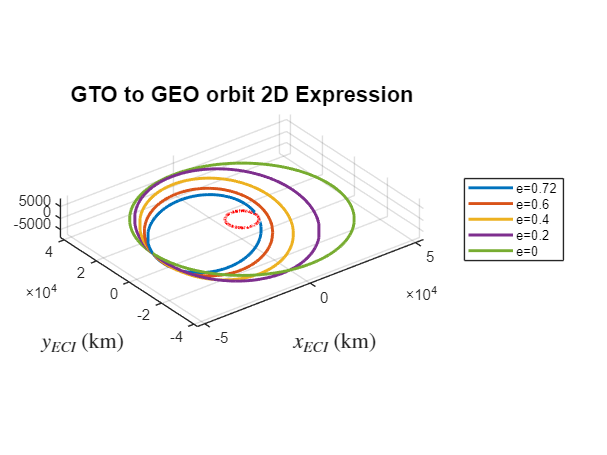

time_vector = [0:1:orbit_period, orbit_period];

figure;
hold on

% Define Orbit Propagator
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)
vel_aps(1) = norm(v(1,:));

% r(end,:)
% v(end,:)
const = SMA * (1 + ecc);

% ecc = 0.6
ecc = 0.6;
inc = 21;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(2) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)



% ecc = 0.4
ecc = 0.4;
inc = 15;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(3) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)

% ecc = 0.2
ecc = 0.2;
inc = 9;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(4) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)



% ecc = 0
ecc = 1e-5;
inc = 0;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(5) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)

% Draw Earth
viscircles([0,0],6378);


axis('equal')
view(3)
legend('e=0.72','e=0.6','e=0.4','e=0.2','e=0','Location','eastoutside')
hold off
title('GTO to GEO orbit 2D Expression','FontSize',15,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15) 
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on

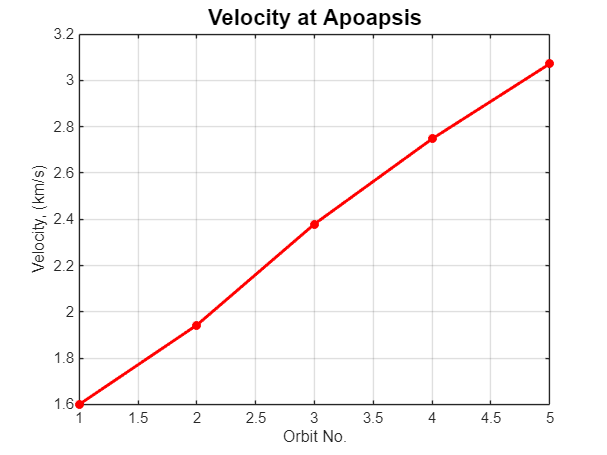



figure;

plot(1:5,vel_aps,'*-','LineWidth',2,'Color','r')
grid on
title('Velocity at Apoapsis','FontSize',15,'FontWeight','bold')
xlabel('Orbit No.')
ylabel('Velocity, (km/s)')

#### II.1.2 Orbital Inclination Change

In a pure inclination change, only the inclination of the orbit is changed while all other orbital characteristics (radius, shape, etc.) remains the same as before. Delta-v($\Delta v_i$) required for an inclination change ($\Delta i$) can be calculated as follows:


$$\begin{array}{l}
\Delta v_i =\frac{2\sin \left(\frac{\Delta i}{2}\right)\left(1+e\;\cos \left(f\right)\right)\textrm{na}}{\sqrt{1-e^2 }\cos \left(\omega +f\right)}\\
e:\textrm{orbital}\;\textrm{eccentricity}\\
\omega :\textrm{argument}\;\textrm{of}\;\textrm{periapsis}\\
f:\textrm{true}\;\textrm{anomaly}\\
n:\textrm{mean}\;\textrm{motion}\\
a:\textrm{semi}-\textrm{major}\;\textrm{axis}
\end{array}$$


  For more complicated maneuvers which may involve a combination of change in inclination and orbital radius, the delta-v is the vector diffference between the velocity vectors of the initial orbit and the desired orbit at the transfer point. These types of combined maneuvers are commonplace, as it is more efficient to perform multiple orbital maneuvers at the same time if these maneuvers have to be done at the same location.

## III. Phase 2: Co-Elliptic Rendezvous with Hohmann Raises


$$\begin{array}{l}
\textrm{Algorithm}\;2\ldotp 1:\;\textrm{Hohmann}\;\textrm{Transfer}\;\textrm{Function}\;\textrm{Design}\\
\textrm{input}\;\textrm{parameter}:\\
\mu =\textrm{standard}\;\textrm{gravitational}\;\textrm{parameter}\;\left(398600\ldotp 4415\right)\\
r_1 =\textrm{starting}\;\textrm{orbit}\;\textrm{radius}\\
r_2 =\textrm{ending}\;\textrm{orbit}\;\textrm{radius}\\
\textrm{output}\;\textrm{parameter}:\\
\Delta v_1 =\textrm{starting}\;\Delta v\;\textrm{for}\;\textrm{departure}\\
\Delta v_2 =\textrm{ending}\;\Delta v\;\textrm{for}\;\textrm{arrival}\\
\textrm{key}\;\textrm{equation}\\
\Delta v_1 =\sqrt{\frac{\mu }{r_1 }}\left(\sqrt{\frac{2r_2 }{r_1 +r_2 }}-1\right)\\
\Delta v_2 =\sqrt{\frac{\mu }{r_2 }}\left(1-\sqrt{\frac{2r_1 }{r_1 +r_2 }}\right)
\end{array}$$


function [delta_v_1, delta_v_2] = hohmann_transfer(r_1, r_2)
mu = 398600.4415;
delta_v_1 = sqrt(mu/r_1) * (sqrt(2*r_2/(r_1+r_2))-1);
delta_v_2 = sqrt(mu/r_2) * (1-sqrt(2*r_1/(r_1+r_2)));
end

### Calculating the effect of Hohmann Raises and Co-Elliptic Motion

  Considering dirction cosine angle for both chaser and target, we can quantify the distance between two satellites. The co-elliptic motion can be divided by two sequence: 1. Co-elliptic motion 2. Hohmann Raise.


$$\begin{array}{l}
\mathbf{Algorithm}\;2\ldotp 2:\mathbf{Trajectory}\;\mathbf{Generation}\;\mathbf{for}\;\mathbf{Hohmann}\;\mathbf{Raise}\;\mathbf{and}\;\mathbf{Co}-\mathbf{Elliptic}\;\mathbf{Motion}\\
\;\;\;\mathrm{Given}\;\mathrm{Constant}\;:{\mathit{\mathbf{r}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{r}}}_{T,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{T,\mathrm{ECI}} \\
\;\;\;\mathrm{get}\;\mathrm{direction}\;\mathrm{cosine}\;\mathrm{angle}:\theta_C ,\theta_T \\
\;\;\;\;\cos \theta_C =\frac{x_{C,\mathrm{ECI}} }{\sqrt{{x^2 }_{C,\mathrm{ECI}} +{y^2 }_{C,\mathrm{ECI}} }}\;,\sin \theta_C =\frac{y_{C,\mathrm{ECI}} }{\sqrt{{x^2 }_{C,\mathrm{ECI}} +{y^2 }_{C,\mathrm{ECI}} }}\\
\;\;\;\;\theta c=\left\lbrace \begin{array}{ll}
\cos^{-1} \left(=\frac{x_{C,\mathrm{ECI}} }{\sqrt{{x^2 }_{C,\mathrm{ECI}} +{y^2 }_{C,\mathrm{ECI}} }}\right) & y_{C,\mathrm{ECI}} \ge 0\\
\cos^{-1} \left(=\frac{x_{C,\mathrm{ECI}} }{\sqrt{{x^2 }_{C,\mathrm{ECI}} +{y^2 }_{C,\mathrm{ECI}} }}\right)+\pi  & y_{C,\mathrm{ECI}} <0
\end{array}\right.\\
\;\;\;\theta_T =\left\lbrace \begin{array}{ll}
\cos^{-1} \left(=\frac{x_{T,\mathrm{ECI}} }{\sqrt{{x^2 }_{C,\mathrm{ECI}} +{y^2 }_{C,\mathrm{ECI}} }}\right) & y_{T,\mathrm{ECI}} \ge 0\\
\cos^{-1} \left(=\frac{x_{T,\mathrm{ECI}} }{\sqrt{{x^2 }_{T,\mathrm{ECI}} +{y^2 }_{T,\mathrm{ECI}} }}\right)+\pi  & y_{T,\mathrm{ECI}} <0
\end{array}\right.\\
\mathrm{Mode}\;1:\mathrm{Co}-\mathrm{Elliptic}\;\mathrm{Motion}\\
\;\;\;\;\;\mathrm{Input}:\Delta t-\mathrm{elapsed}\;\mathrm{time}\\
\;\;\;\;\mathrm{Output}:{\mathit{\mathbf{r}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{r}}}_{T,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{T,\mathrm{ECI}} \;\mathrm{vector}\;\mathrm{by}\;\Delta t\;\left(\mathrm{two}\;\mathrm{body}\;\mathrm{propagation}\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\mathit{\mathbf{r}}}_{\mathrm{LVLH}} ,{\mathit{\mathbf{v}}}_{\mathrm{LVLH}\;} \;\mathrm{vector}\;\mathrm{by}\;\Delta t\;\left(\mathrm{ECI}\;\mathrm{to}\;\mathrm{LVLH}\;\mathrm{coordinate}\;\mathrm{transform}\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{incidance}\;\mathrm{angle}\;\mathrm{difference}\;\theta_T -\theta_C \;\mathrm{by}\;\Delta t\\
\\
\mathrm{Mode}\;2:\mathrm{Hohmann}\;\mathrm{Raise}\\
\;\;\;\mathbf{Input}:r_2 \\
\;\;\;\mathbf{Output}:\Delta v_1 ,\Delta v_2 ,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{updated}} \;,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{final}\;} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\mathit{\mathbf{r}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{r}}}_{T,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{T,\mathrm{ECI}} \;\mathrm{vector}\;\mathrm{by}\;\Delta t\;\left(\mathrm{two}\;\mathrm{body}\;\mathrm{propagation}\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;{\mathit{\mathbf{r}}}_{\mathrm{LVLH}} ,{\mathit{\mathbf{v}}}_{\mathrm{LVLH}\;} \;\mathrm{vector}\;\mathrm{by}\;\Delta t\;\left(\mathrm{ECI}\;\mathrm{to}\;\mathrm{LVLH}\;\mathrm{coordinate}\;\mathrm{transform}\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{incidance}\;\mathrm{angle}\;\mathrm{difference}\;\theta_T -\theta_C \;\mathrm{by}\;\Delta t\\
\\
\;\;\;r_1 =\left|{\mathit{\mathbf{r}}}_{C,\mathrm{ECI}} \right|,\Delta v_1 =\sqrt{\frac{\mu }{r_1 }}\left(\sqrt{\frac{2r_2 }{r_1 +r_2 }}-1\right)\\
\;\;\;\;{\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{updated}} ={\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} +\left\lbrack 0,\Delta v_1 ,0\right\rbrack \\
\;\;\;\;\Delta t=\pi \sqrt{\frac{{\left(\frac{r_1 +r_2 }{2}\right)}^3 }{\mu }}\;\;{\mathit{\mathbf{r}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} ,{\mathit{\mathbf{r}}}_{T,\mathrm{ECI}} ,{\mathit{\mathbf{v}}}_{T,\mathrm{ECI}} ,\;{\mathit{\mathbf{r}}}_{\mathrm{LVLH}} ,{\mathit{\mathbf{v}}}_{\mathrm{LVLH}\;} \;\mathrm{vector}\;\mathrm{by}\;\Delta t\\
\;\;\mathrm{substitute}\;\mathrm{last}\;\mathrm{row}\;\mathrm{of}\;{\mathit{\mathbf{v}}}_{C,\mathrm{ECI}} \;\mathrm{to}\;\;\;{\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{final}\;} \\
\;\;\;\Delta v_2 =\sqrt{\frac{\mu }{r_2 }}\left(1-\sqrt{\frac{2r_1 }{r_1 +r_2 }}\right)\\
\;\;{\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{final}=\;} {\mathit{\mathbf{v}}}_{C,\mathrm{ECI},\mathrm{Last}\_\mathrm{row}} +\left\lbrack 0,\Delta v_2 ,0\right\rbrack 
\end{array}$$


## IV. Phase 3:  Walking Safety Ellipse (WSE) Approach

  The linearized Hill's equations approximate the relative motion of two spacecraft in an unperturbed point-mass gravitational field:


$$\begin{array}{l}
\ddot{x} -2n\dot{y} -3n^2 x=0\\
\ddot{y} +2n\dot{x} =0\\
\ddot{z} +n^2 z=0
\end{array}$$


  The mean motion, $n$, of the reference spacecraft is given in terms of the central body gravitation parameter, $\mu$, and the referecne spacecraft semi-major axis, $a$, by the equation


$$n=\sqrt{\mu /a^3 }$$


  The linearized equationf of motion can be solved analytically:


$$\begin{array}{l}
x\left(t\right)=\frac{{\dot{x} }_0 }{n}\sin \;\textrm{nt}-\left(3x_0 +\frac{2{\dot{y} }_0 }{n}\right)\cos \;\textrm{nt}+4x_0 +\frac{2{\dot{y} }_0 }{n}\\
y\left(t\right)=\frac{{2\dot{x} }_0 }{n}\cos \;\textrm{nt}+\left(6x_0 +\frac{4{\dot{y} }_0 }{n}\right)\sin \;\textrm{nt}-\left(6nx_0 +3{\dot{y} }_0 \right)t-\frac{2{\dot{x} }_0 }{n}+y_0 \\
z\left(t\right)=\frac{{\dot{z} }_0 }{n}\sin \;\textrm{nt}+z_0 \;\cos \;\textrm{nt}
\end{array}$$


   From this equation, we can extract key characteristics of the relative spacraft motion: 

- **Chaser spacecraft maintains elliptical motion relative to target spacecraft, and vice versa**

  Therefore, we will characterize **safety ellipse** from given inertial position and velocity vectors of chaser and target spacecraft to understand the relative motion.

 
$$\begin{array}{l}
\left\lbrack \textrm{Safety}\;\textrm{Ellipse}\;\textrm{Parameters}\right\rbrack \\
x_{\max } :\textrm{minor}\;\textrm{axis}\;\textrm{of}\;\textrm{the}\;\textrm{in}-\textrm{plane}\;\textrm{ellipse}\;\textrm{or}\;\textrm{maximum}\;\textrm{radial}\;\textrm{offset}\\
y_{\max } :\textrm{major}\;\textrm{axis}\;\textrm{of}\;\textrm{the}\;\textrm{in}-\textrm{plane}\;\textrm{ellipse}\;\textrm{or}\;\textrm{maximum}\;\textrm{in}-\textrm{track}\;\textrm{offset}\\
z_{\max } :\textrm{magnitude}\;\textrm{of}\;\textrm{the}\;\textrm{out}-\textrm{of}\;\textrm{plane}\;\textrm{motion}\\
x_c :\textrm{Instantanous}\;\textrm{mean}\;\textrm{radial}\;\textrm{offset}\;\textrm{of}\;\textrm{relative}\;\textrm{motion}\;\\
y_c :\textrm{Instantanous}\;\textrm{mean}\;\textrm{in}-\textrm{track}\;\textrm{offset}\;\textrm{of}\;\textrm{relative}\;\textrm{motion}\;\\
{\dot{y} }_c :\textrm{The}\;\textrm{drift}\;\textrm{rate}\;\textrm{of}\;\textrm{the}\;\textrm{mean}\;\textrm{offset}\;\textrm{in}\;\textrm{the}\;\textrm{velocity}\;\textrm{direction}\;\\
\alpha :\textrm{Phase}\;\textrm{angle}\;\textrm{of}\;\textrm{the}\;\textrm{in}-\textrm{plane}\;\textrm{motion}\\
\beta :\textrm{Phase}\;\textrm{angle}\;\textrm{of}\;\textrm{the}\;\textrm{out}-\textrm{of}-\textrm{plane}\;\textrm{motion}\\
\textrm{note}:\textrm{RIC}\;\textrm{frame}\;\textrm{is}\;\left(\textrm{Radial},\textrm{In}-\textrm{track},\textrm{Cross}-\textrm{track}\right)\;\textrm{frame},\textrm{which}\;\textrm{is}\;\textrm{equivalent}\;\textrm{to}\;\textrm{LVLH}\;\textrm{in}\;\textrm{circular}\;\textrm{orbit}\;\textrm{of}\;\textrm{target}\;\textrm{vehicle}
\end{array}$$


 
$$\begin{array}{l}
\left\lbrack \textrm{Algorithm}\;3\ldotp 1:\textrm{Get}\;\textrm{Safety}\;\textrm{Ellipse}\;\textrm{Parameters}\;\textrm{from}\;\textrm{relative}\;\textrm{position}\;\textrm{and}\;\textrm{velocity}\right\rbrack \\
\textrm{given}:x_0 ,y_0 ,z_0 ,{\dot{x} }_0 ,{\dot{y} }_0 ,{\dot{z} }_0 ,n=\sqrt{\mu /a^3 }\\
\textrm{output}\;\textrm{parameter}:x_{\max } ,y_{\max } ,z_{\max } ,x_c ,y_c ,z_c ,{\dot{y} }_c ,\alpha ,\beta \\
x_{\max } =\sqrt{{\left(\frac{{\dot{x} }_0 }{n}\right)}^2 +{\left(3x_0 +\frac{2{\dot{y} }_0 }{n}\right)}^2 }=\sqrt{{\left(\frac{1}{2}\left(y_c -y_0 \right)\right)}^2 +{\left(x_c -x_0 \right)}^2 }\\
y_{\max } =2x_{\max } \\
z_{\max } =\sqrt{{\left(\frac{{\dot{z} }_0 }{n}\right)}^2 +{\left(z_0 \right)}^2 }\\
x_c =4x_0 +\frac{2{\dot{y} }_0 }{n}\\
y_c =-\frac{2{\dot{x} }_0 }{n}+y_0 \\
{\dot{y} }_c =-\left(6nx_0 +3{\dot{y} }_0 \right)\;\left(\textrm{It}\;\textrm{is}\;\textrm{important}\;\textrm{to}\;\textrm{know}\;{\dot{\mathit{\mathbf{y}}} }_{\mathit{\mathbf{c}}} =-\frac{3\mathit{\mathbf{n}}}{2}{\mathit{\mathbf{x}}}_{\mathit{\mathbf{c}}} \right)\\
\cos \alpha =-\frac{1}{x_{\max } }\left(3x_0 +\frac{2{\dot{y} }_0 }{n}\right),\;\;\sin \alpha =-\frac{1}{x_{\max } }\left(\frac{{\dot{x} }_0 }{n}\right)\\
\Rightarrow \alpha =\left\lbrace \begin{array}{ll}
\cos^{-1} \left(-\frac{1}{x_{\max } }\left(3x_0 +\frac{2{\dot{y} }_0 }{n}\right)\right) & \left(\left.\textrm{if}\;\;\sin \alpha \ge 0\right)\right)\\
\cos^{-1} \left(-\frac{1}{x_{\max } }\left(3x_0 +\frac{2{\dot{y} }_0 }{n}\right)\right)+\pi  & \left(\left.\textrm{if}\;\;\sin \alpha <0\right)\right)
\end{array}\right.\\
\cos \beta =\frac{z_0 }{z_{\max } },\sin \beta =-\frac{1}{z_{\max } }\frac{{\dot{z} }_0 }{n}\\
\Rightarrow \beta =\left\lbrace \begin{array}{ll}
\cos^{-1} \left(\frac{z_0 }{z_{\max } }\right) & \left(\textrm{if}\;\;\sin \beta \ge 0\right)\\
\cos^{-1} \left(\frac{z_0 }{z_{\max } }\right)+\pi  & \left(\textrm{if}\;\sin \left(\beta \right)<0\right)
\end{array}\right.\\
\begin{array}{l}
\textrm{Therefore},\textrm{we}\;\textrm{can}\;\textrm{get}\\
\;\;\;x\left(t\right)=x_{\max } \cos \left(\textrm{nt}+\alpha \right)+x_c \\
\;\;\;y\left(t\right)=-2x_{\max } \sin \left(\textrm{nt}+\alpha \right)+y_c +{\dot{y} }_c t\\
\;\;\;z\left(t\right)=z_{\max } \cos \left(\textrm{nt}+\beta \right)
\end{array}
\end{array}$$


  For designing this safety ellipse from mission requirement and calcuate required delta-v, we should create the function to do this.


$$\begin{array}{l}
\left\lbrack \textrm{Algorithm}\;3\ldotp 2:\textrm{Get}\;\textrm{relative}\;\textrm{velocity}\;\textrm{graph}\;\textrm{from}\;\textrm{given}\;\textrm{Safety}\;\textrm{Ellipse}\;\textrm{Parameters}\right\rbrack \\
\textrm{given}\;\textrm{constant}:x_0 ,y_0 ,z_0 ,\;n=\sqrt{\mu /a^3 }\\
\textrm{control}\;\textrm{input}\;\textrm{parameter}:x_c ,y_c ,z_{\max } \;\left(\textrm{or}\;y_c \;,{\dot{y} }_c ,z_{\max } \right)\\
\textrm{output}\;\textrm{parameter}:{\dot{x} }_0 ,{\dot{y} }_0 ,{\dot{z} }_0 ,x_{\max } ,y_{\max } ,{\dot{y} }_c \;\left(\textrm{or}\;x_c \right),\alpha ,\beta \\
{\dot{x} }_0 =-\frac{n}{2}y_c +\frac{n}{2}y_0 \;\;\;\;\textrm{from}\;y_c =-\frac{2{\dot{x} }_0 }{n}+y_0 \\
{\dot{y} }_0 =\frac{n}{2}x_c -2nx_0 \;\;\;\;\textrm{from}\;\;x_c =4x_0 +\frac{2{\dot{y} }_0 }{n}\;\\
\Rightarrow \textrm{we}\;\textrm{can}\;\textrm{know}\;{\dot{x} }_0 ,{\dot{y} }_0 \;\textrm{are}\;\textrm{first}\;\textrm{order}\;\textrm{function}\;w\ldotp r\ldotp t\;x_c \;\textrm{and}\;y_c \\
{\dot{z} }_0 =\pm n\sqrt{z_{\max }^2 -z_0^2 }\\
x_{\max } =\sqrt{{\left(\frac{1}{2}\left(y_c -y_0 \right)\right)}^2 +{\left(x_c -x_0 \right)}^2 }\;\;\left(\textrm{We}\;\textrm{can}\;\textrm{define}\;x_{\max } \;\textrm{as}\;\textrm{control}\;\textrm{parameter}\right)\\
y_{\max } =\sqrt{{\left(y_c -y_0 \right)}^2 +{\left(2\left(x_c -x_0 \right)\right)}^2 }=2x_{\max } \\
{\dot{y} }_c =-\frac{3n}{2}x_c \to \textrm{From}\;\textrm{this}\;\textrm{linear}\;\textrm{relation},\textrm{we}\;\textrm{can}\;\textrm{define}\;\textrm{control}\;\textrm{parameter}\;\textrm{as}\;\left(y_c \;,{\dot{y} }_c ,z_{\max } \right)\\
\cos \alpha =-\frac{1}{x_{\max } }\left(x_c -x_0 \right),\;\;\sin \alpha =-\frac{1}{x_{\max } }\left(\frac{1}{2}\left(y_c -y_0 \right)\right)\\
\cos \beta =\frac{z_0 }{z_{\max } },\sin \beta =-\frac{1}{z_{\max } }\frac{{\dot{z} }_0 }{n}
\end{array}$$
 


$$\begin{array}{l}
\left\lbrack \textrm{Algorithm}\;3\ldotp 3:\mathbf{G}\textrm{et}\;\textrm{relative}\;\textrm{velocity}\;\textrm{requirement}\;\textrm{from}\;\textrm{given}\;\textrm{Safety}\;\textrm{Ellipse}\;\textrm{Parameters}\right\rbrack \\
\;\;\;\textrm{given}\;\textrm{constant}:x_0 ,y_0 ,z_0 ,\;n=\sqrt{\mu /a^3 }\\
\;\;\;\textrm{control}\;\textrm{parameter}:{\dot{y} }_c ,x_{\max } ,z_{\max } \\
\;\;\;\textrm{output}\;\textrm{parameter}:{\dot{x} }_0 ,{\dot{y} }_0 ,{\dot{z} }_0 ,x_c ,y_c ,{\dot{y} }_c ,\;\alpha ,\beta \\
\textrm{Step}\;1:\textrm{Decide}\;\textrm{value}\;\textrm{of}\;{\dot{\mathit{\mathbf{y}}} }_{\mathit{\mathbf{c}}} \left(\textrm{Approaching}\;\textrm{velocity}\;\textrm{of}\;\textrm{center}\;\textrm{of}\;\textrm{ellipse}\right)\to \textrm{get}\;x_c \;,{\dot{y} }_0 \\
\;\;\;\textrm{control}\;\textrm{input}\;1:{\dot{y} }_c \;\to \textrm{output}{\;x}_c \;,{\dot{y} }_0 \\
\;\;\;\textrm{output}\;1\ldotp 1:\;x_c =-\frac{2}{3n}{\dot{y} }_c \to \textrm{altitude}\;\textrm{difference},\textrm{different}\;\textrm{orbital}\;\textrm{period}\\
\;\;\;\textrm{output}\;1\ldotp 2:{\dot{y} }_0 =-\frac{1}{3}{\dot{y} }_c -2n\;x_0 \;\left(\textrm{linear}\;\textrm{relationship}\;\textrm{with}\;x_c :{\dot{y} }_0 =\frac{n}{2}x_c -2nx_0 \right)\\
\textrm{Step}\;2:\textrm{Decide}\;\textrm{value}\;\textrm{of}\;{\mathit{\mathbf{x}}}_{\max } \;\left({\mathit{\mathbf{y}}}_{\max } \right)\to \textrm{Size}\;\textrm{of}\;\textrm{the}\;\textrm{Ellipse}\\
\;\;\;\textrm{control}\;\textrm{input}\;2:x_{\max } \left(=\frac{1}{2}y_{\max } \right)\to \textrm{output}\;y_c ,{\dot{x} }_0 \\
\;\;\;\textrm{output}\;2\ldotp 1:{\dot{x} }_0 =\pm n\sqrt{x_{\max }^2 -{\left(x_c -x_0 \right)}^2 }\\
\;\;\;\textrm{output}\;2\ldotp 2:y_c =y_0 \mp 2\sqrt{x_{\max }^2 -{\left(x_c -x_0 \right)}^2 }\\
\;\;\;\textrm{note}:x_{\max } \ge \left|x_c -x_0 \right|\\
\textrm{Step}\;3:\textrm{Decide}\;\textrm{value}\;\textrm{of}\;{\mathit{\mathbf{z}}}_{\max } \\
\;\;\;\textrm{control}\;\textrm{input}\;3:z_{\max } \to \textrm{output}\;{\dot{z} }_0 \\
\;\;\;\textrm{output3}\ldotp 1:\;{\dot{z} }_0 =\pm n\sqrt{z_{\max }^2 -z_0^2 }\\
\textrm{Step}\;4:\textrm{Get}\;\textrm{phase}\;\textrm{angle}\;\alpha ,\beta \;\textrm{for}\;\textrm{get}\;\textrm{relationship}\;\textrm{between}\;\mathit{\mathbf{x}}\left(\mathit{\mathbf{t}}\right)\;\textrm{and}\;\mathit{\mathbf{z}}\left(\mathit{\mathbf{t}}\right)\\
\;\;\;\cos \alpha =-\frac{1}{x_{\max } }\left(x_c -x_0 \right),\;\;\sin \alpha =-\frac{1}{x_{\max } }\left(\frac{1}{2}\left(y_c -y_0 \right)\right)\;\left(x\left(t\right)=x_{\max } \cos \left(\textrm{nt}+\alpha \right)+x_c \right)\\
\;\;\;\cos \beta =\frac{z_0 }{z_{\max } },\sin \beta =-\frac{1}{z_{\max } }\frac{{\dot{z} }_0 }{n}\;\;\left(z\left(t\right)=z_{\max } \cos \left(\textrm{nt}+\beta \right)\right)\\
\Rightarrow \textrm{Instead}\;\textrm{of}\;{\mathit{\mathbf{z}}}_{\max } ,\;\textrm{we}\;\textrm{can}\;\textrm{set}\;\textrm{control}\;\textrm{input}\;\textrm{as}\;\beta \;\textrm{to}\;\textrm{get}\;{\mathit{\mathbf{z}}}_{\max } \;\textrm{and}\;{\dot{\mathit{\mathbf{z}}} }_0 \\
\;\;\;\textrm{control}\;\textrm{input}:\beta \\
\;\;\;\textrm{output}\;4\ldotp 1:\;z_{\max } =\frac{z_0 }{\cos \beta }\;\\
\;\;\;\textrm{output}\;4\ldotp 2:{\dot{z} }_0 =-nz_0 \tan \beta 
\end{array}$$


### Coordinate Transform between ECI and LVLH


$$\begin{array}{l}
\textrm{Algorithm}\;3\ldotp 4:\textrm{Transfer}\;\textrm{between}\;\textrm{ECI}\iff \textrm{LVLH}\\
\textrm{given}\;\textrm{constants}:\;{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \;,{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} \;,n=\sqrt{\mu /a^3 }\\
\textrm{Step}\;1:\textrm{get}\;\textrm{rotation}\;\textrm{matrix}\;\mathit{\mathbf{Q}}\;\textrm{between}\;\textrm{IJK}\iff \textrm{ijk}\\
\;\;\;\hat{i} =\frac{{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} }{\left|\;{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \right|}\;,\hat{k} =\frac{{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \times {\mathit{\mathbf{v}}}_{T,\textrm{ECI}} }{\left|{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \times {\mathit{\mathbf{v}}}_{T,\textrm{ECI}} \right|},\hat{j} =\frac{\hat{k} \times \hat{i} }{\left|\hat{k} \times \hat{i} \right|}\\
\;\;\;Q_{\textrm{LVLH},\textrm{ECI}} =\left\lbrack \begin{array}{c}
{\hat{i} }^T \\
{\hat{j} }^T \\
{\hat{k} }^T 
\end{array}\right\rbrack \;\;,Q_{\textrm{ECI},\textrm{LVLH}} =\left\lbrack \begin{array}{ccc}
| & | & |\\
\hat{i}  & \hat{j}  & \hat{k} \\
| & | & |
\end{array}\right\rbrack \\
\\
\textrm{Step}\;2:\textrm{ECI}\to \textrm{LVLH}\\
\;\;\;\textrm{input}:{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \;,{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} \;,{\mathit{\mathbf{r}}}_{C,\textrm{ECI}} \;,{\mathit{\mathbf{v}}}_{C,\textrm{ECI}} \\
\;\;\;\textrm{output}:{\mathit{\mathbf{r}}}_{\textrm{LVLH}} \;,{\mathit{\mathbf{v}}}_{\textrm{LVLH}} \\
\;\;\;{\mathit{\mathbf{r}}}_{\textrm{LVLH}} =Q_{\textrm{LVLH},\textrm{ECI}} \left({\mathit{\mathbf{r}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \right)\\
\;\;\;{\mathit{\mathbf{v}}}_{\textrm{LVLH}} =Q_{\textrm{LVLH},\textrm{ECI}} \left\lbrace {\mathit{\mathbf{v}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} -\vec{\Omega} \times \left({\mathit{\mathbf{r}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \right)\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=Q_{\textrm{LVLH},\textrm{ECI}} \left\lbrace {\mathit{\mathbf{v}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} -n\hat{k} \times \left({\mathit{\mathbf{r}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \right)\right\rbrace \\
\\
\textrm{Step}\;3:\textrm{LVLH}\to \textrm{ECI}\\
\;\;\;\textrm{input}:{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \;,{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} ,{\mathit{\mathbf{r}}}_{\textrm{LVLH}} ,{\mathit{\mathbf{v}}}_{\textrm{LVLH}} \\
\;\;\;\textrm{output}:{\mathit{\mathbf{r}}}_{C,\textrm{ECI}} \;,{\mathit{\mathbf{v}}}_{C,\textrm{ECI}} \\
\;\;\;{\mathit{\mathbf{r}}}_{C,\textrm{ECI}} =Q_{\textrm{ECI},\textrm{LVLH}} \;{\mathit{\mathbf{r}}}_{\textrm{LVLH}} +{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \\
\;\;\;{\mathit{\mathbf{v}}}_{C,\textrm{ECI}} =Q_{\textrm{ECI},\textrm{LVLH}} {\mathit{\mathbf{v}}}_{\textrm{LVLH}} +{\mathit{\mathbf{v}}}_{T,\textrm{ECI}} +n\hat{k} \times \left({\mathit{\mathbf{r}}}_{C,\textrm{ECI}} -{\mathit{\mathbf{r}}}_{T,\textrm{ECI}} \right)
\end{array}$$


## IV. Phase 4: Capture Axis approach

Using two-impulse / glideslope approach method (Lambert's method for relative orbit elements)

## Two Impulse Rendezvous Procedure

### II.1 I/O Structure


$$\begin{array}{l}
\textrm{Input}\;\textrm{Parameter}\\
\;-\textrm{Position}\;\textrm{and}\;\textrm{velocity}\;\textrm{of}\;\textrm{Taget}\;\textrm{Satellite}:r_{\textrm{target}} ={\mathit{\mathbf{r}}}_0 \;,v_{\textrm{target}} ={\mathit{\mathbf{v}}}_0 \\
\;-\textrm{Kepler}\;\textrm{parameter}\;\textrm{of}\;\textrm{Chaser}\;\textrm{Satellite}:{\mathit{\mathbf{r}}}_{\textrm{chaser}} =\mathit{\mathbf{r}},{\mathit{\mathbf{v}}}_{\textrm{chaser}} =\mathit{\mathbf{v}}\\
\;-\textrm{Required}\;\textrm{Elapsed}\;\textrm{Time}\;t_f \\
\;\;\left(\textrm{note}:\textrm{Target}\;\;\textrm{Satellite}\;\textrm{shall}\;\textrm{maintain}\;\textrm{circular}\;\textrm{orbit}\right)\\
\\
\textrm{Output}\;\textrm{Parameter}\\
\;-\textrm{initial}\;{\left\lbrack \Delta \mathit{\mathbf{v}}\right\rbrack }_{\textrm{LVLH}} \;\textrm{and}\;\textrm{final}\;{\left\lbrack \Delta \mathit{\mathbf{v}}\right\rbrack }_{\textrm{LVLH}} \;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;-\delta \mathit{\mathbf{r}}\left(\mathit{\mathbf{t}}\right)\;\textrm{and}\;\delta \mathit{\mathbf{v}}\left(\mathit{\mathbf{t}}\right)\;\textrm{data}\;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\\
\;-\textrm{initial}\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ \;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{ECI}\;\textrm{frame}\;\textrm{for}\;\textrm{orbit}\;\textrm{propagation}\\
\left(\textrm{Note}\;:\textrm{the}\;\textrm{actual}\;\textrm{path}\;\textrm{should}\;\textrm{be}\;\textrm{drawn}\;\textrm{in}\;\textrm{ECI}\;\textrm{frame}\;\textrm{for}\;\textrm{cross}\;\textrm{check}\right)
\end{array}$$


### II.2 Two Impulse Rendezvous Algorithm


$$\begin{array}{l}
\mathrm{Step}\;1\ldotp \mathrm{Generate}\;\mathrm{Clohessy}-\mathrm{Wiltshire}\;\mathrm{matrices}\;\mathrm{function}\;\mathrm{for}\;\mathrm{given}\;\mathrm{mean}\;\mathrm{motion}\\
\;\;\left\lbrack \Phi_{\mathrm{rr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
4-3\cos \;nt & 0 & 0\\
6\left(\;\sin \;nt-nt\right) & 1 & 0\\
0 & 0 & \cos \;nt
\end{array}\right\rbrack \;\;\;\left\lbrack \Phi_{\mathrm{rv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\frac{\sin \;nt}{n} & \frac{2}{n}\left(1-\cos \;nt\right) & 0\\
\frac{2}{n}\left(\cos \;nt-1\right) & \frac{4}{n}\sin \;nt-3t & 0\\
0 & 0 & \frac{1}{n}\sin \;nt
\end{array}\right\rbrack \\
\;\;\left\lbrack \Phi_{\mathrm{vr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
3n\;\sin \;nt & 0 & 0\\
6n\left(\cos \;nt-1\right) & 0 & 0\\
0 & 0 & -n\;\sin \;nt
\end{array}\right\rbrack \;\;\left\lbrack \Phi_{\mathrm{vv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;nt & 2\;\sin \;nt & 0\\
-2\;\sin \;nt & 4\cos \;nt-3 & 0\\
0 & 0 & \cos \;nt
\end{array}\right\rbrack \\
\\
\mathrm{Step}\;2\ldotp \mathrm{From}\;\mathrm{given}\;t_f ,\mathrm{find}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \;\mathrm{and}\;\mathrm{corresponding}\;\left\lbrack \Delta {\mathit{\mathbf{v}}}_0 \right\rbrack \;\mathrm{wrt}\;\mathrm{LVLH}\;\mathrm{frame}\\
\;\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack =-{\left\lbrack \Phi_{\mathrm{rv}} \left(t_f \right)\right\rbrack }^{-1} \left\lbrack \Phi_{\mathrm{rr}} \left(t_f \right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack \\
\;\;\;{\left\lbrack \Delta {\mathit{\mathbf{v}}}_0 \right\rbrack }_{\mathrm{LVLH}} =\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack -\left\lbrack \delta {\mathit{\mathbf{v}}}_0^- \right\rbrack 
\end{array}$$



$$\begin{array}{l}
3\ldotp \mathrm{At}\;\mathrm{time}\;t_f ,\mathrm{find}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_f^- \right\rbrack \;\mathrm{and}\;\mathrm{corresponding}\;\left\lbrack \Delta {\mathit{\mathbf{v}}}_f \right\rbrack \;\mathrm{wrt}\;\mathrm{LVLH}\;\mathrm{frame}\\
\;\;\left\lbrack \delta {\mathit{\mathbf{v}}}_f^- \right\rbrack =\left\lbrack \Phi_{\mathrm{vr}} \left(t_f \right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack +\left\lbrack \Phi_{\mathrm{vv}} \left(t_f \right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;{\left\lbrack \Delta {\mathit{\mathbf{v}}}_f \right\rbrack }_{\mathrm{LVLH}} =-\left\lbrack \delta {\mathit{\mathbf{v}}}_f^- \right\rbrack \\
\\
4\ldotp \mathrm{From}\;t=0~t_f ,\mathrm{we}\;\mathrm{can}\;\mathrm{calculate}\;\;{\left\lbrack \delta \mathit{\mathbf{r}}\right\rbrack }_{\mathrm{LVLH}} \;\mathrm{and}\;{\left\lbrack \delta \mathit{\mathbf{v}}\right\rbrack }_{\mathrm{LVLH}} \;\mathrm{from}\;\mathrm{given}\;\mathrm{equation}\\
\;\;\left\lbrack \delta \mathit{\mathbf{r}}\left(t\right)\right\rbrack =\left\lbrack \Phi_{\mathrm{rr}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack +\left\lbrack \Phi_{\mathrm{rv}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{v}}}_0 \right\rbrack \\
\;\;\left\lbrack \delta \mathit{\mathbf{v}}\left(t\right)\right\rbrack =\left\lbrack \Phi_{\mathrm{vr}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack +\left\lbrack \Phi_{\mathrm{vv}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{v}}}_0 \right\rbrack \\
\\
5\ldotp \mathrm{From}\;\mathrm{LVLH}\;\mathrm{to}\;\mathrm{ECI}\;\mathrm{coordinate}\;\mathrm{transfer},\mathrm{we}\;\mathrm{can}\;\mathrm{calculate}\;{\mathit{\mathbf{v}}}_{\mathrm{ECI}}^+ \;\mathrm{from}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\mathrm{from}\;\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_0 +\Omega_{\mathrm{Target}} \times {\mathit{\mathbf{r}}}_{\mathrm{rel}} +{\mathit{\mathbf{v}}}_{\mathrm{rel}} \\
\;\;\;{\mathit{\mathbf{v}}}_{\mathrm{ECI}}^+ ={\mathit{\mathbf{v}}}_0 +\Omega_{\mathrm{Target}} \times \delta \mathit{\mathbf{r}}+{\left\lbrack \mathit{\mathbf{Q}}\right\rbrack }_{\mathrm{LVLH},\mathrm{ECI}}^{-1} \left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\left(\mathrm{note}:{\mathit{\mathbf{v}}}_0 ={\mathrm{Target}}^{\prime } s\;\mathrm{veclotiy}\;\mathrm{wrt}\;\mathrm{ECI},\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack ={\mathrm{Chaser}}^{\prime } s\;\mathrm{relative}\;\mathrm{velocity}\;\mathrm{wrt}\;{\mathrm{target}}^{\prime } s\;\mathrm{LVLH}\right)\;\;
\end{array}$$


## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end

## Appendix 3: Transfer between ECI and LVLH

function delta_r_LVLH = eci2lvlh(delta_r_eci, r_eci, v_eci)
  
    % Reference Frame of the Target
    i_hat = r_eci/norm(r_eci);
    k_hat = cross(r_eci, v_eci) / norm(cross(r_eci, v_eci));
    j_hat = cross(k_hat,i_hat);
    
    % Transformation Matrix from ECI to Space Station Frame
    Q_LVLH_ECI = [i_hat';j_hat';k_hat'];
    delta_r_LVLH = Q_LVLH_ECI * delta_r_eci;
end
